# Signaler och system - Laboration 2

**Uppgift 4:**

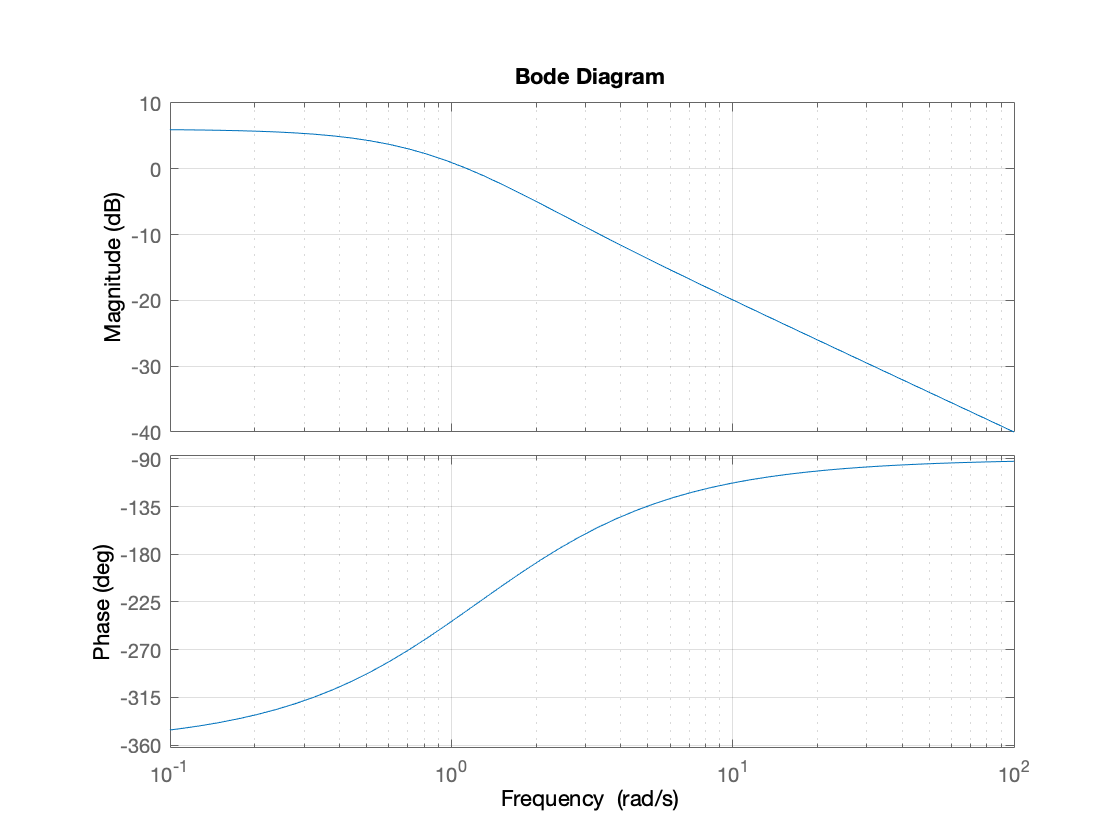

%Y = (1*s^1+2*s^0);
%X = (1*s^2-2*s^1+1*s^0);


bode([1,2],[1,-2,1]); grid;

**Uppgift 5:**

D = 20*log(9);
A = 10^(D/20);

**Uppgift 7:**

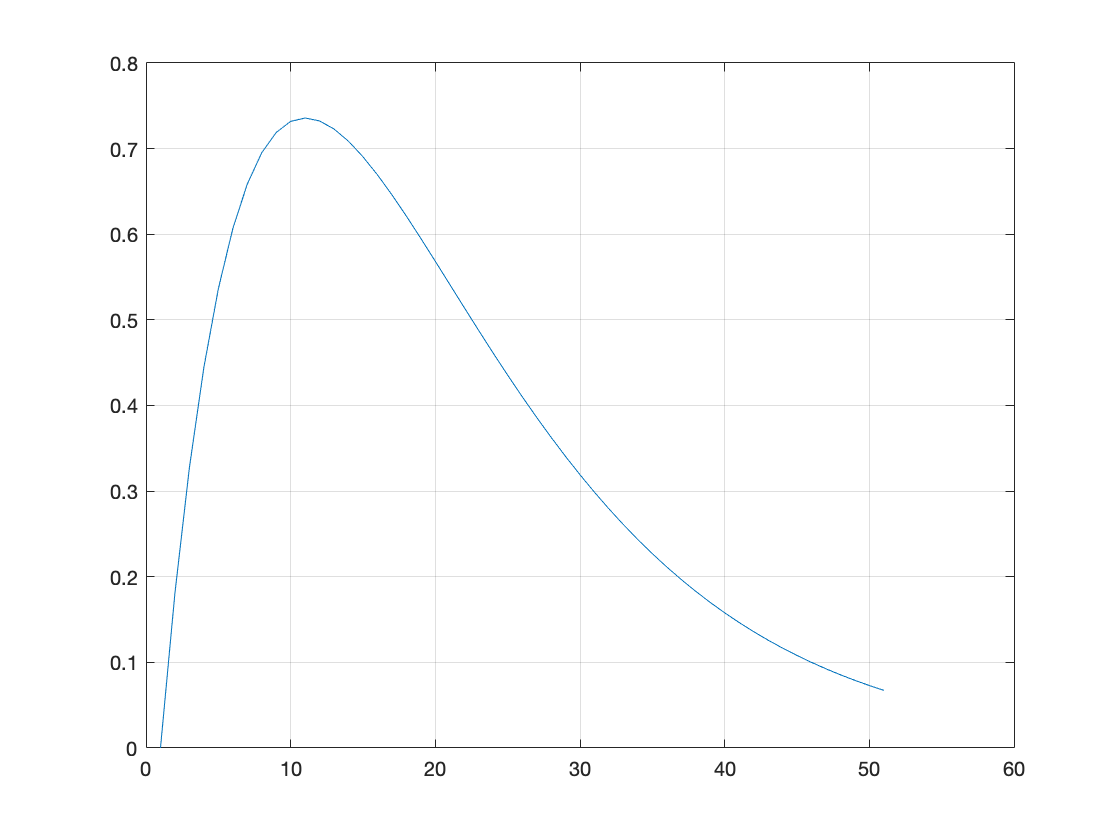

t=0:0.1:5;
y=2.*t.*exp(-t);
figure (1); plot(y); grid;

**Uppgift 8:**

%Beräkna antal steg i index n
N=5/0.1;

%Skapa stegfunktion
u=exp(-t)

u =     1.0000    0.9048    0.8187    0.7408    0.6703    0.6065    0.5488    0.4966    0.4493    0.4066    0.3679    0.3329    0.3012    0.2725    0.2466    0.2231    0.2019    0.1827    0.1653    0.1496    0.1353    0.1225    0.1108    0.1003    0.0907    0.0821    0.0743    0.0672    0.0608    0.0550    0.0498    0.0450    0.0408    0.0369    0.0334    0.0302    0.0273    0.0247    0.0224    0.0202    0.0183    0.0166    0.0150    0.0136    0.0123    0.0111    0.0101    0.0091    0.0082    0.0074


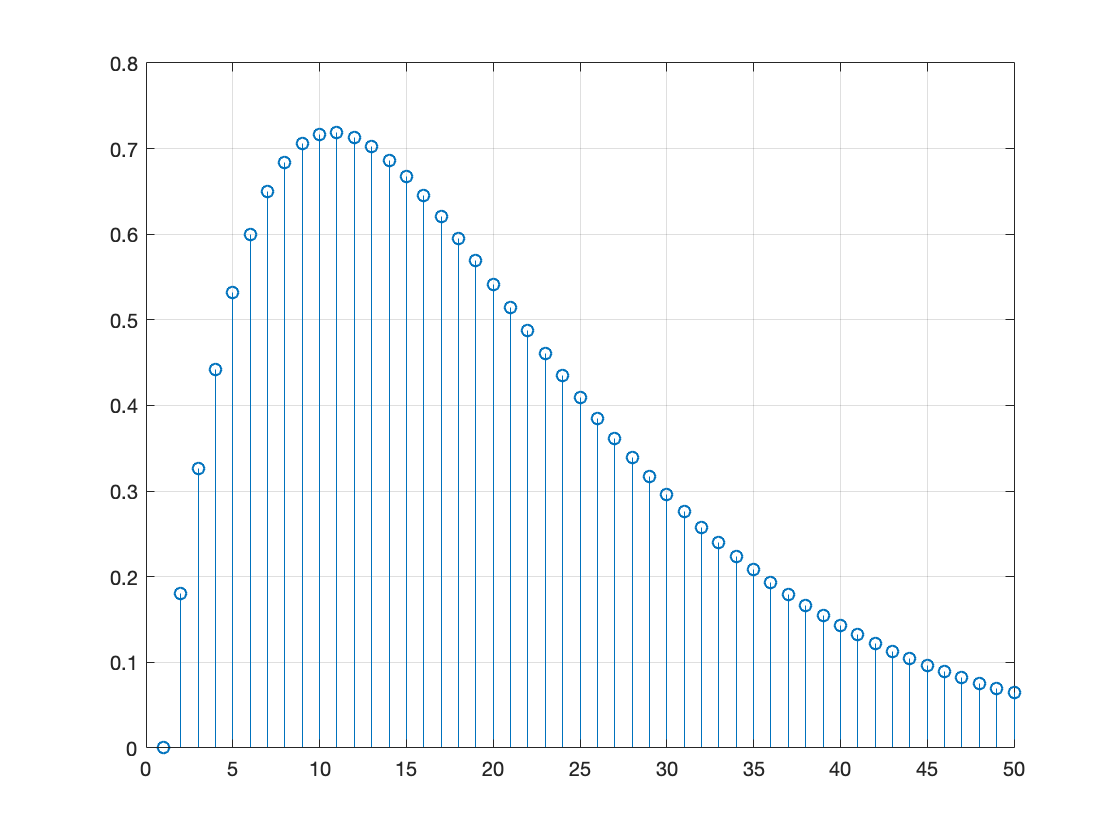


for m=2:N
    y(m)=0.9*y(m-1)+0.2*u(1,m);
end

%Rita resultatet
figure(2); stem(y); grid; xlim([0 50]);

**Uppgift 9:**

%Exakt samma funktion som kommer se likadan ut som upg 8

**Uppgift 10:**

clear all

N=5/0.1;
Ts=0.1

Ts = 0.1000

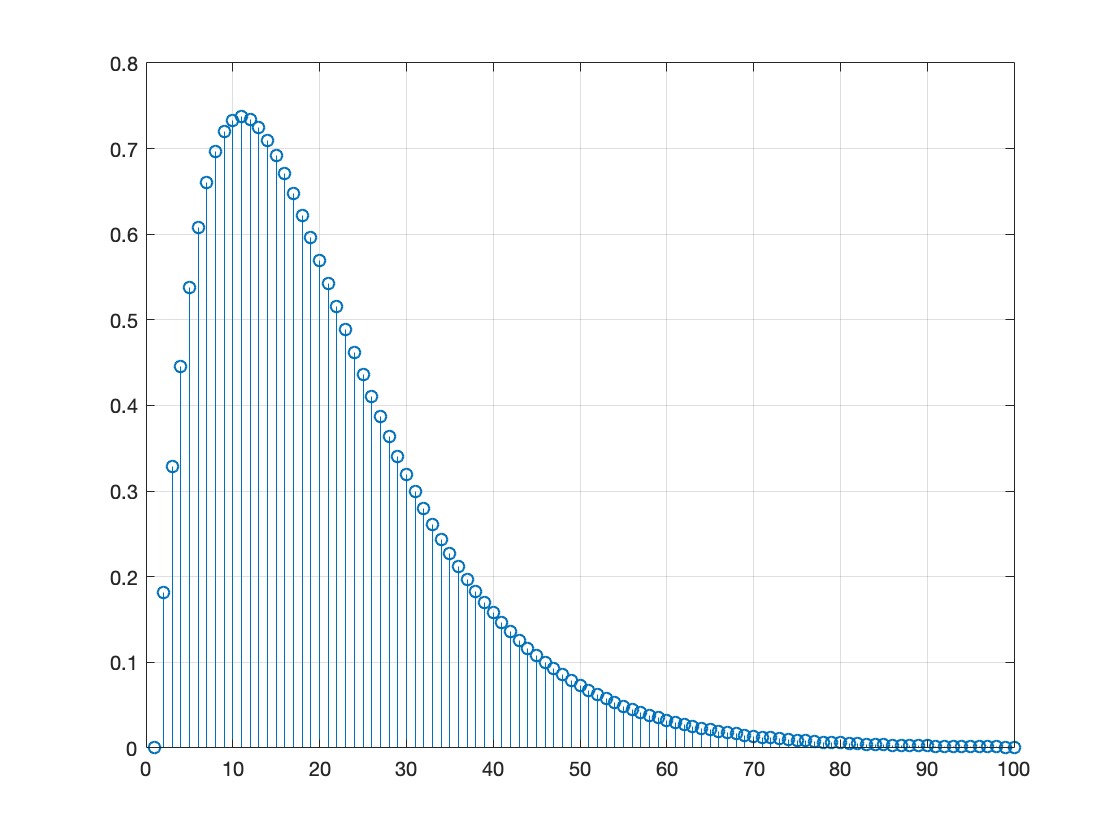

t=0:Ts:10;
y=zeros(1,101);
x=exp(-t);

for m=2:101
    y(m)=(0.2*x(m)+0.2*x(m-1)+1.9*y(m-1))/2.1;
end

%Rita resultatet
figure(3); stem(y); grid; xlim([0 100]);

**Uppgift 11:**

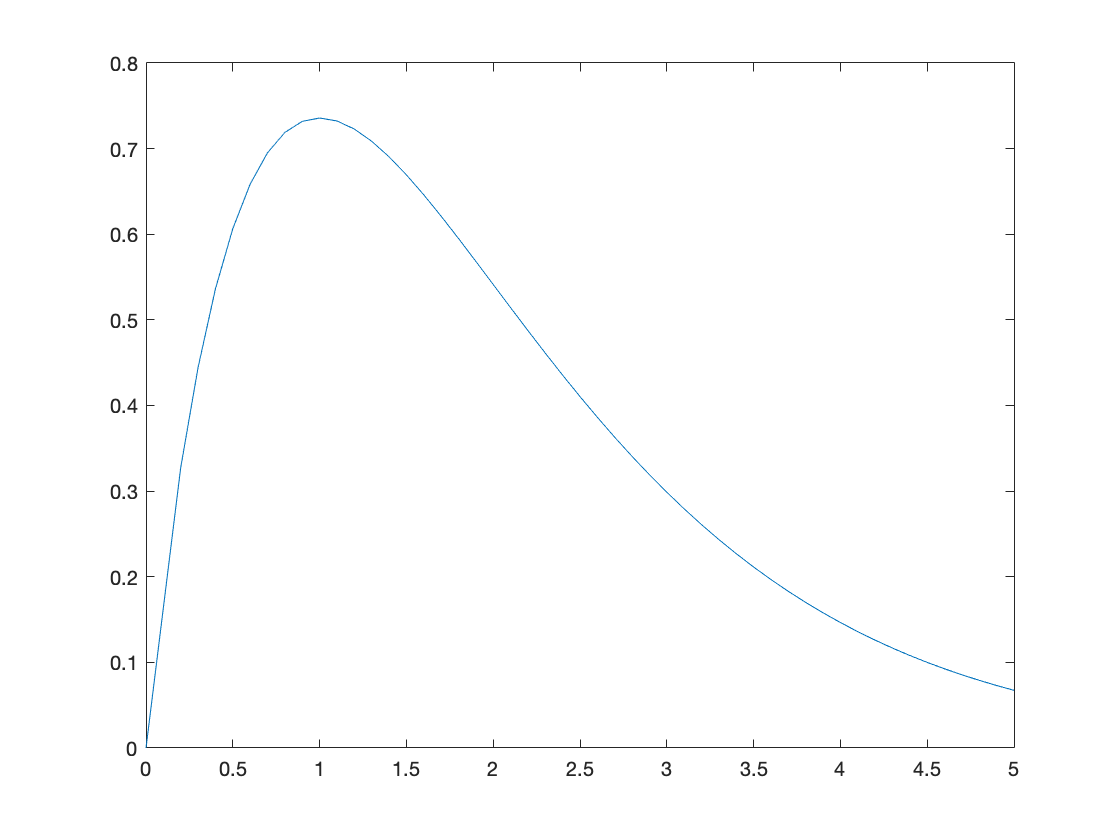

clear all
syms s;
Y = 2/(s+1)^2;
y = ilaplace(Y);

for n = 2 :1:50
    t = 0.1*n;                  % Skapa t-värde 
    y_numerisk(n) = eval(y);    % Funk. ''ekval'' utnyttjar t-värdet
    t2(n) = t;  % Spara t-värde 
end

plot(t2, y_numerisk);